# ECE 203 Lab 3: Generate Sinusoids using one_cos Function

### ### Agam Goyal ###

# Live Script containing skeleton code for Lab Activity 3 created by Talha Sultan, 02/2021 #

## Part (a): Define Input Parameters to one_cos Function

% Complete the following lines of Code 
% Uncomment to run

% Amplitude of Input Sinusoid
A = 70  % units

A = 70


% Frequency of Input Sinusoid
omega = 200*pi % radians/sec

omega = 628.3185


% Phase of Input Sinusoid
phi = pi/2 % radians

phi = 1.5708


% Duration of 
dur = 0.06 % sec

dur = 0.0600

## Part (b): Call one_cos function

% Complete the following lines of Code 
% Uncomment to run

% Call the one_cos function and save output variables
% Complete the following lines of code and uncomment to run
[x,t] = one_cos(A, omega, phi, dur) 

x =     0.0000  -21.6312  -41.1450  -56.6312  -66.5740  -70.0000  -66.5740  -56.6312  -41.1450  -21.6312   -0.0000   21.6312   41.1450   56.6312   66.5740   70.0000   66.5740   56.6312   41.1450   21.6312    0.0000  -21.6312  -41.1450  -56.6312  -66.5740  -70.0000  -66.5740  -56.6312  -41.1450  -21.6312   -0.0000   21.6312   41.1450   56.6312   66.5740   70.0000   66.5740   56.6312   41.1450   21.6312    0.0000  -21.6312  -41.1450  -56.6312  -66.5740  -70.0000  -66.5740  -56.6312  -41.1450  -21.6312


t =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245



% Complete the following lines of code and uncomment to run

% Display the one_cos output for certain indices

% Output time at specified index
index = 51

index = 51

t_at_index = t(index)

t_at_index = 0.0250


disp(['The value of the time vector at index ', num2str(index), ' is: '  num2str(t_at_index) ' seconds']);

The value of the time vector at index 51 is: 0.025 seconds



% Output sinusoid value at specified index
index2 = 120

index2 = 120

x_at_index = x(index2)

x_at_index = 21.6312


disp(['The value of the sinusoid vector at index ' num2str(index2) ' is: '  num2str(x_at_index, 5) ' units']);

The value of the sinusoid vector at index 120 is: 21.631 units


## Part (c): Plot the Sinusoid

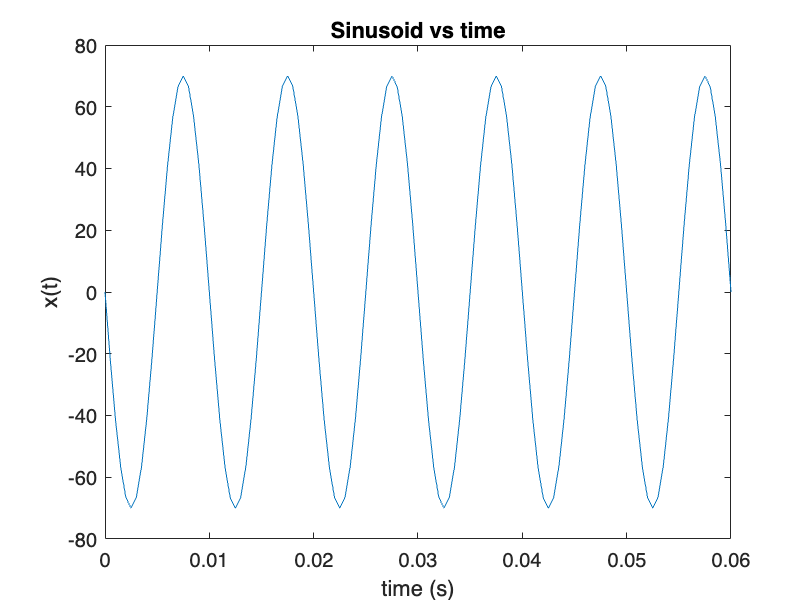

% Complete the following lines of Code 
% Uncomment to run

% Plot
% Complete the following lines of code and uncomment to run

figure;
plot(t, x)
hold on;
title('Sinusoid vs time'); 
xlabel('time (s)'); ylabel('x(t)');
hold off 

## **Sum of Sinusoids**

[x1,t] = one_cos(11, 202*pi, -pi/3, 0.06);
[x2,t] = one_cos(20, 202*pi, pi/6, 0.06);

x_sum = x1 + x2;

% Check values
x1(96)

ans = -9.5263

x2(87)

ans = -14.8629

x_sum(14)

ans = -13.0303

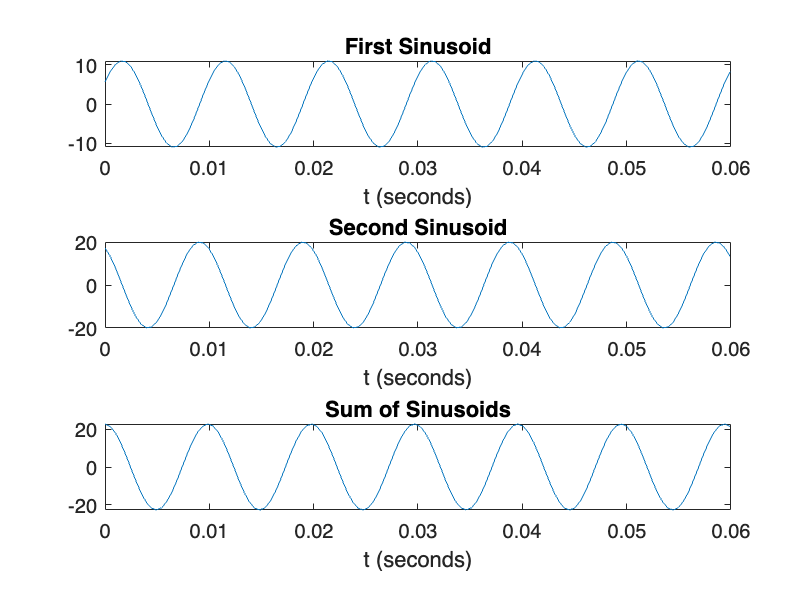


% Plotting
subplot(3,1,1), plot(t, x1)
xlabel('t (seconds)');
title('First Sinusoid');
subplot(3,1,2), plot(t, x2)
xlabel('t (seconds)');
title('Second Sinusoid');
subplot(3,1,3), plot(t, x_sum)
xlabel('t (seconds)');
title('Sum of Sinusoids');

## Next Part

[y,t] = one_cos(22.825, 202*pi, 0.020756, 0.06);
y(48)

ans = -13.7966

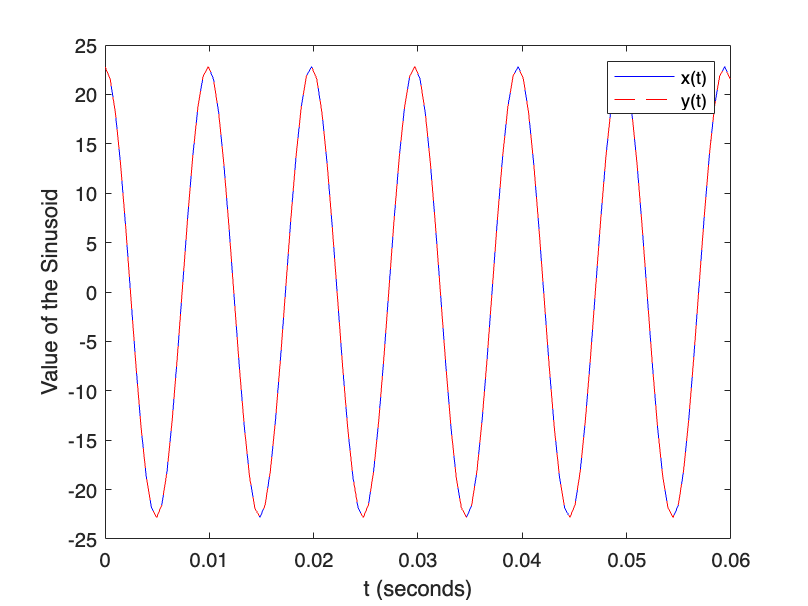


% Plotting
figure, plot(t,x_sum, "b-", t, y, "r--")
xlabel('t (seconds)');
ylabel('Value of the Sinusoid')
legend(["x(t)" "y(t)"])